# Chromaticity tutorial

Illustrate the chromaticity values, starting from the XYZ plots.

- We read in the XYZ functions and plot the spectral XYZ values in 3-space

- Add the chromaticity values into the plot

- Change the view to front-facing

- Call that chromaticityPlot utility

## Initialize

ieInit;

## Read in the CIE XYZ functions

xyz = ieReadSpectra('XYZEnergy.mat');

Plot the XYZ functions in 3-space as blue 'o'.  Add the lines that will be the boundary of the chromaticity coordinates in the end.  These connect the corners of the unit triangle in XYZ space (i.e., X + Y + Z = 1).

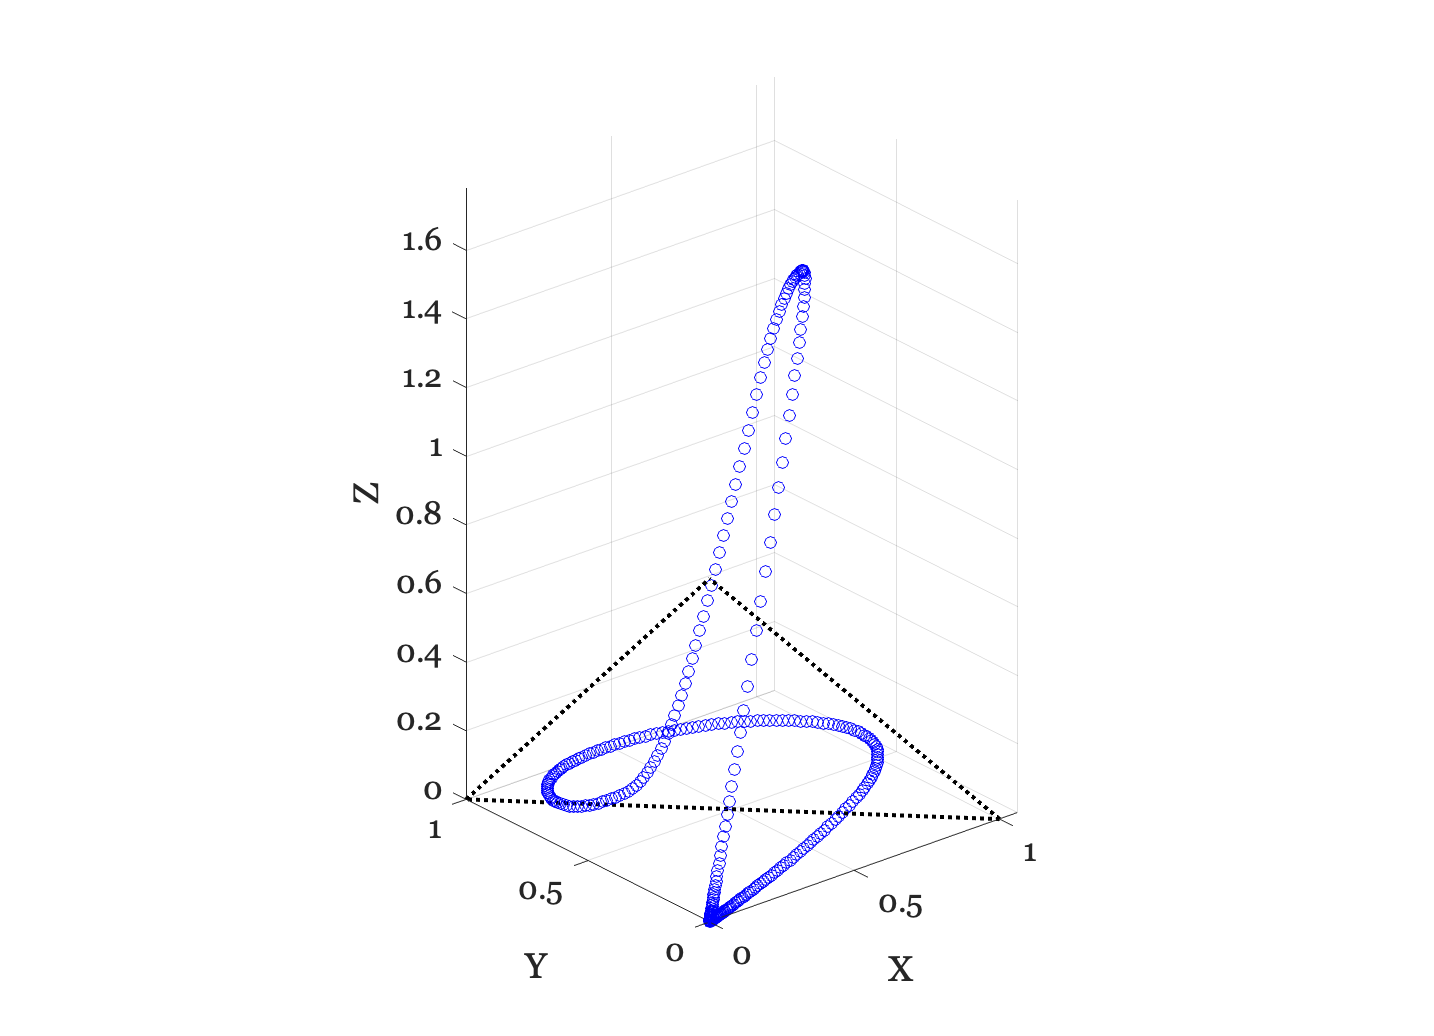

ieNewGraphWin;
P1 = plot3(xyz(:,1),xyz(:,2),xyz(:,3),'bo');
grid on; axis square; axis equal
xlabel('X'),ylabel('Y'),zlabel('Z');

line([1 0],[0 1],[0 0],'Color','k','Linestyle',':','Linewidth',2);  % X to Y
line([1 0],[0 0],[0 1],'Color','k','Linestyle',':','Linewidth',2);  % X to Z
line([0 0],[1 0],[0 1],'Color','k','Linestyle',':','Linewidth',2);     % Y to Z
view([-40,25]);

## Add the corresponding chromaticity points

We calculate the chromaticity values of each spectral XYZ.  Then we calculate the z value, which is 1 -x - y. Finally, we plot the chromaticity points as green 'x'.

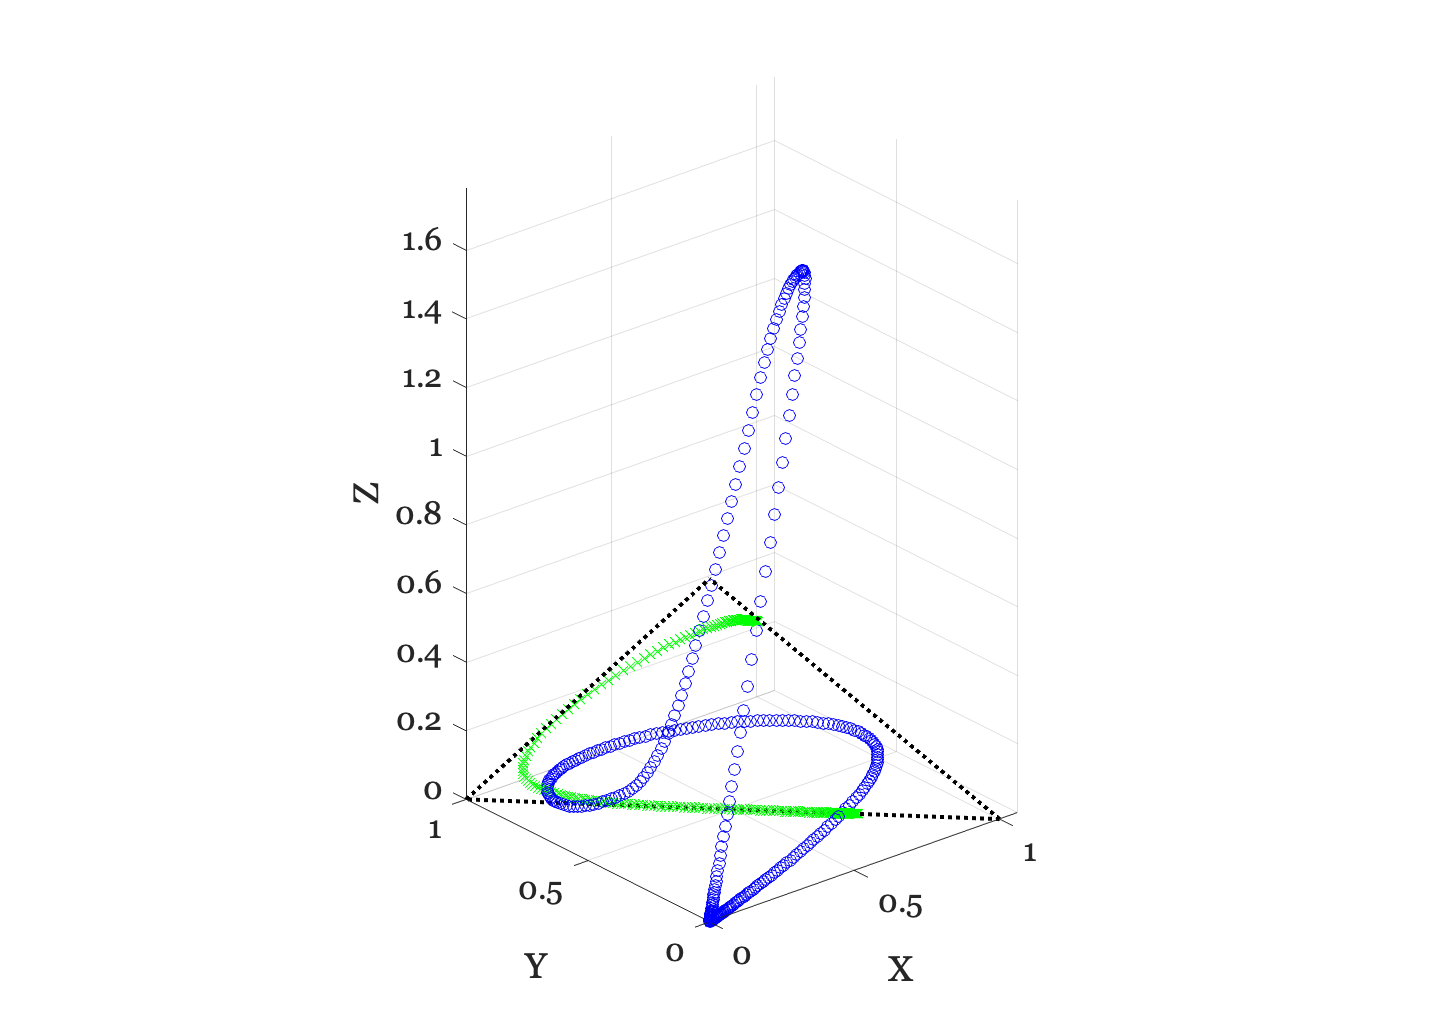

xy = chromaticity(xyz);
z = ones(length(xy(:,1)),1) - xy(:,1) - xy(:,2);
hold on;
plot3(xy(:,1),xy(:,2),z(:,1),'x');

## XY view

Change the view so we are looking at the XY plane.

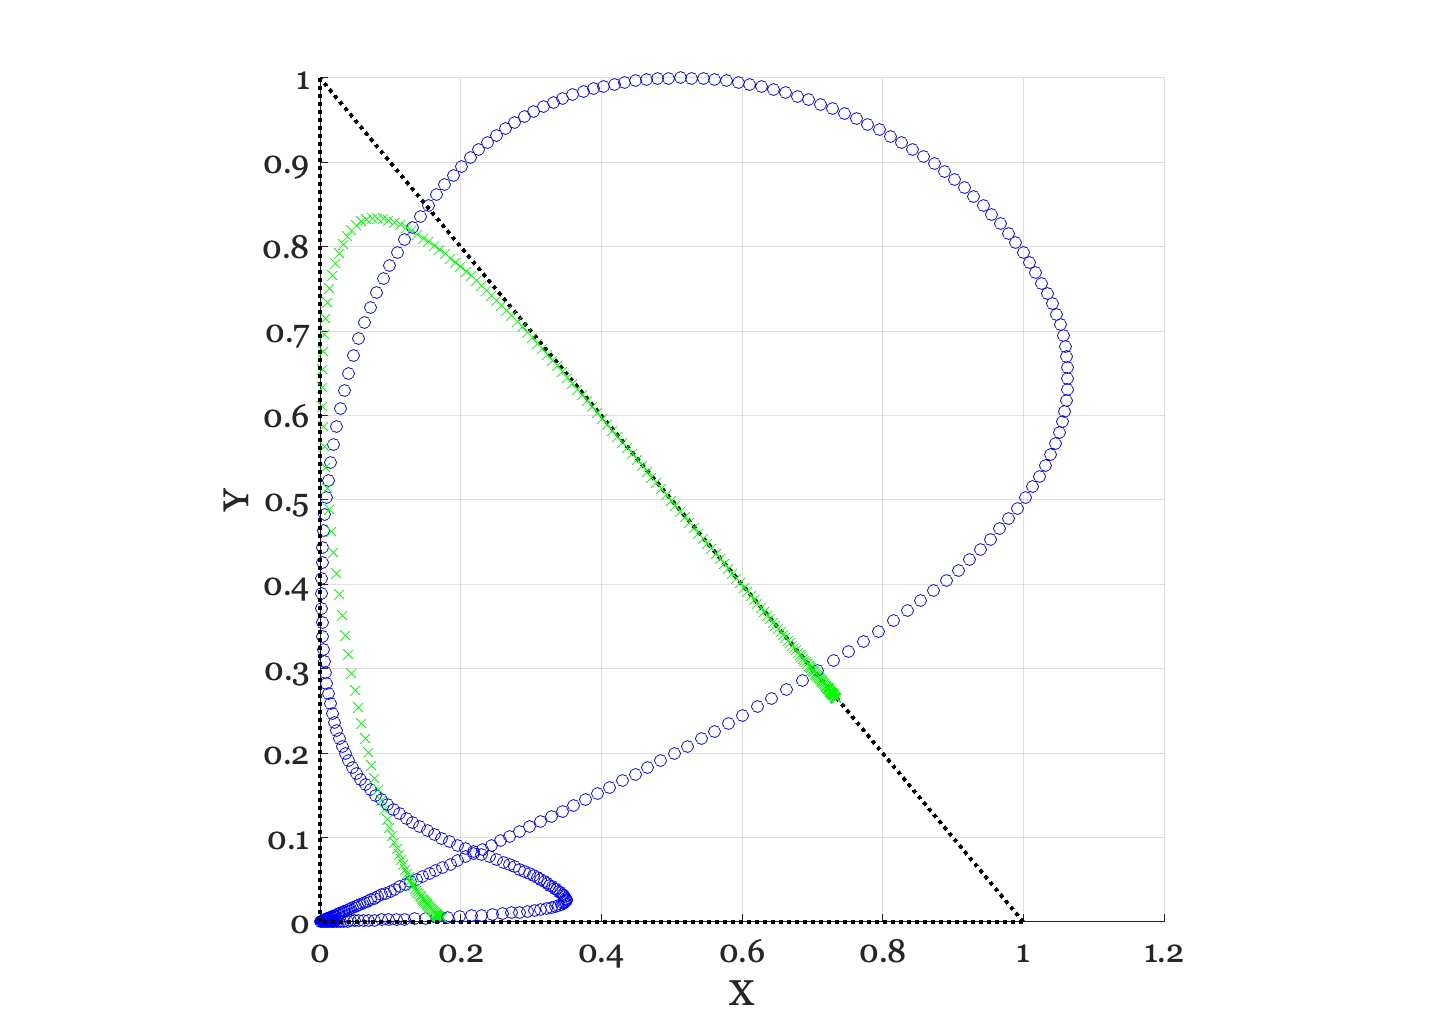

view([0 90]);

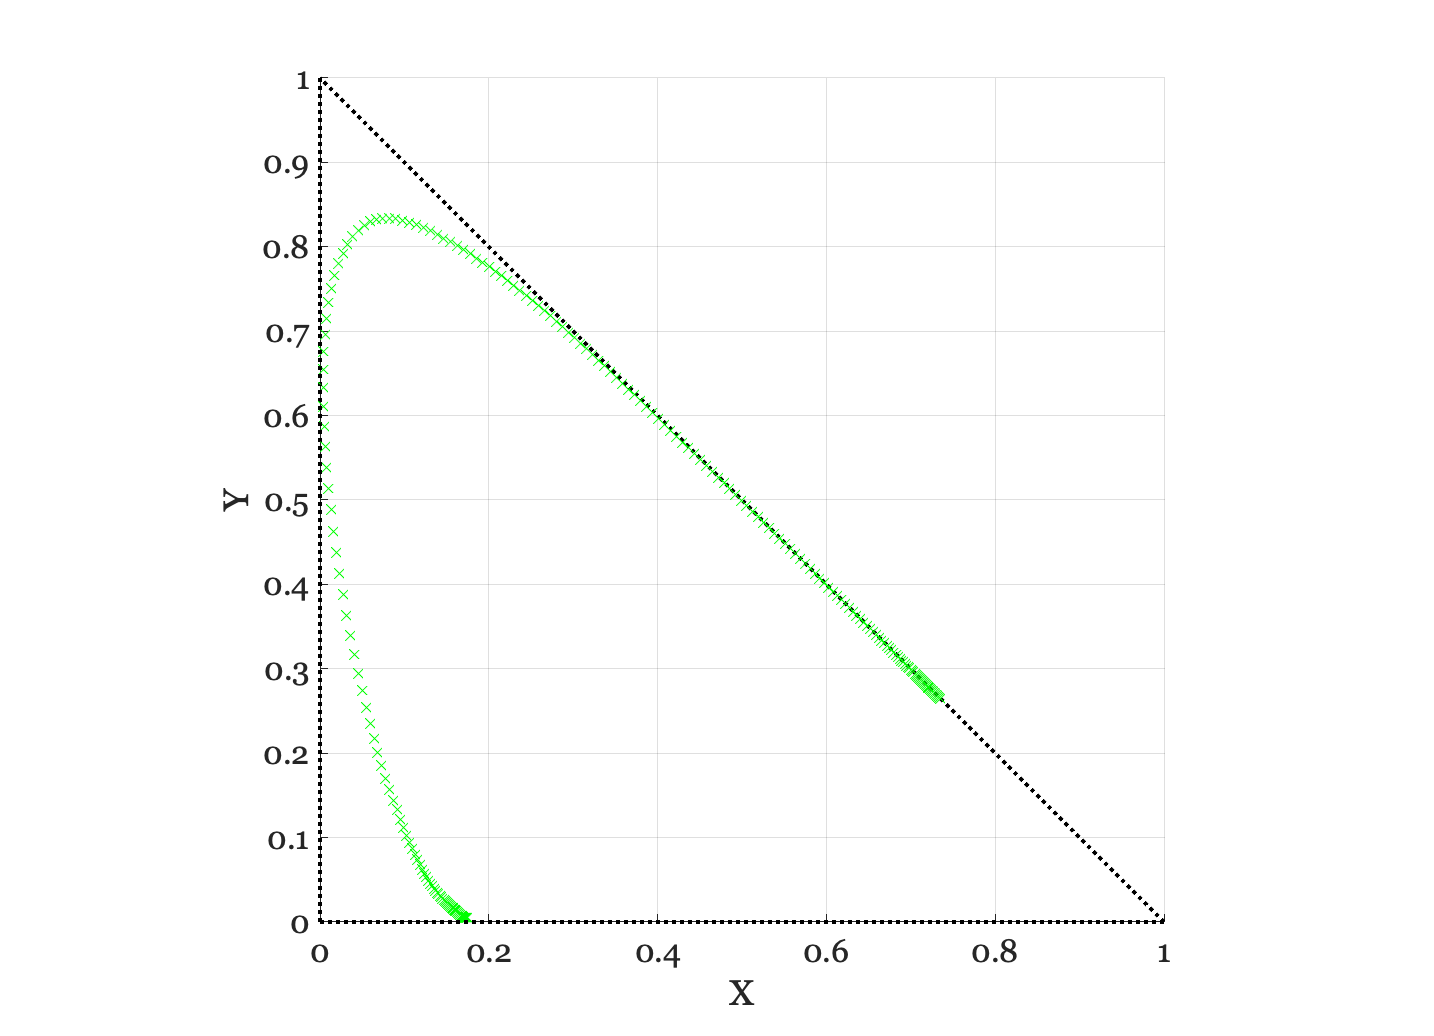

delete(P1);

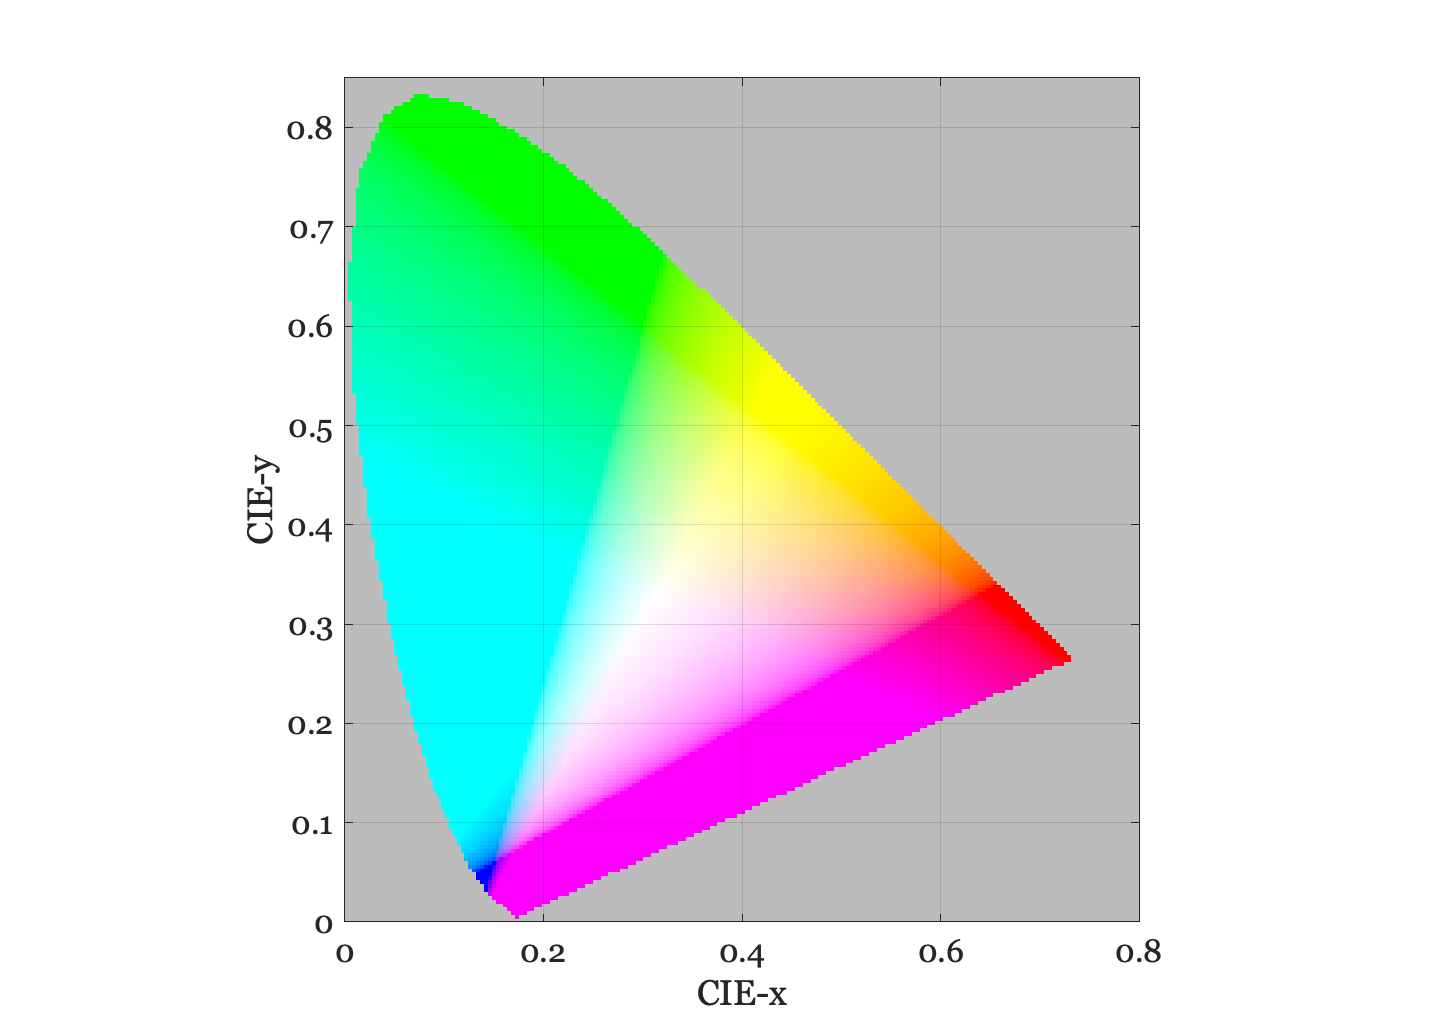

chromaticityPlot;